Gaussian Noise and Wiener Filter

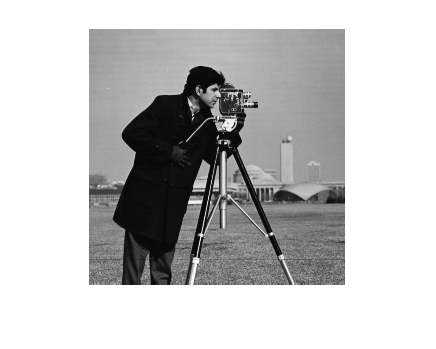

cameramanImage = imread("cameraman.tif");
cameramanImageWithNoise = imnoise(cameramanImage, 'gaussian', 0.01);
 
figure, imshow(cameramanImage);

title("Original image"); 
figure, imshow(cameramanImageWithNoise);
title("Image with noise");

standardDeviation = 3;
cutoff = ceil(standardDeviation * 3);

gaussianFilter = fspecial('gaussian', (2 * cutoff + 1), standardDeviation);
gaussianFilteredImage = conv2(cameramanImage, gaussianFilter, "same");
gaussianFilteredNoiseImage = conv2(cameramanImageWithNoise, gaussianFilter, "same");

figure, imshow(gaussianFilteredImage/256);
title("Gaussian filtered original image"); 
figure, imshow(gaussianFilteredNoiseImage/256);
title("Gaussian filtered noise image");

wienerFilteredImage = wiener2(cameramanImageWithNoise, [5, 5]);
figure, imshow(wienerFilteredImage);
title("Wiener filtered noise image");
